clear; clc;

## get datacube

root_path = 'D:\files\spectral_analysis\mat_demo\data\nir1115\';
seed_variety = 'jh';
file_name0 = 125;
file_name = num2str(file_name0);

% file path
hdr_path_name = strcat(root_path, seed_variety, file_name, '_RT.hdr');
raw_path_name = strcat(root_path, seed_variety, file_name, '_RT.raw');

% get dimensions and waves
info = get_info(hdr_path_name);
[samples, lines, bands, wavelengths] = get_dimensions(info)

samples =    320


lines =    538


bands =    256


wavelengths =        930.79       936.97       943.16       949.35       955.54       961.73       967.92       974.11        980.3        986.5       992.69       998.89       1005.1       1011.3       1017.5       1023.7       1029.9       1036.1       1042.3       1048.5       1054.7       1060.9       1067.1       1073.4       1079.6       1085.8         1092       1098.2       1104.4       1110.7       1116.9       1123.1       1129.3       1135.5       1141.8         1148       1154.2       1160.5       1166.7       1172.9       1179.2       1185.4       1191.6       1197.9       1204.1       1210.3       1216.6       1222.8       1229.1       1235.3


% get datacube

tic

rawdata = get_rawdata(raw_path_name);
rawcube0 = reshape(rawdata, [samples, bands, lines]); % contrast order to python
rawcube = permute(rawcube0, [3, 1, 2]);

toc

历时 0.084935 秒。


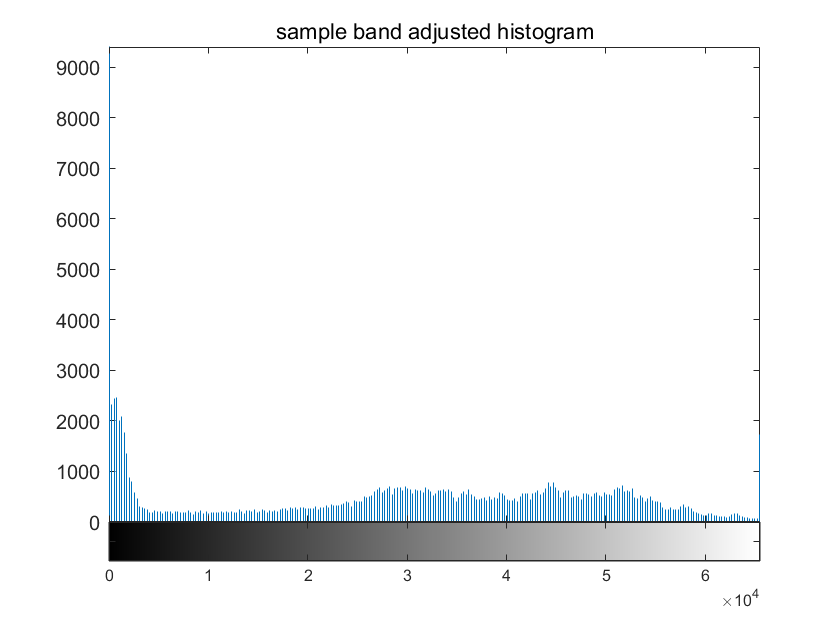

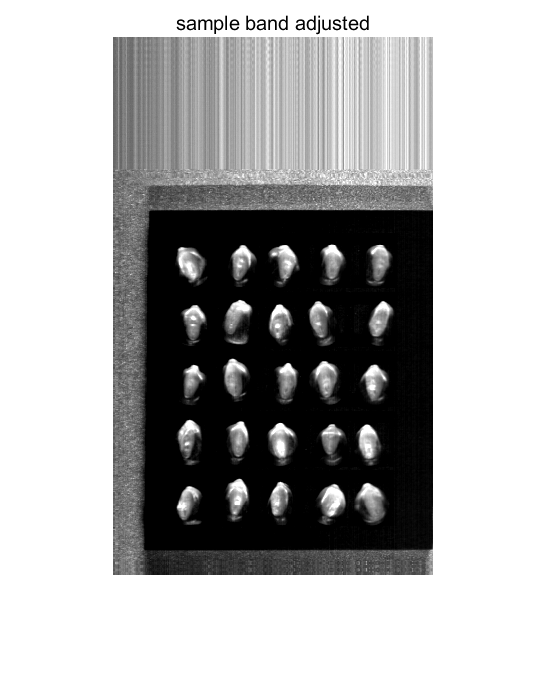

% band display  %% handi
display_band(rawcube, 100);

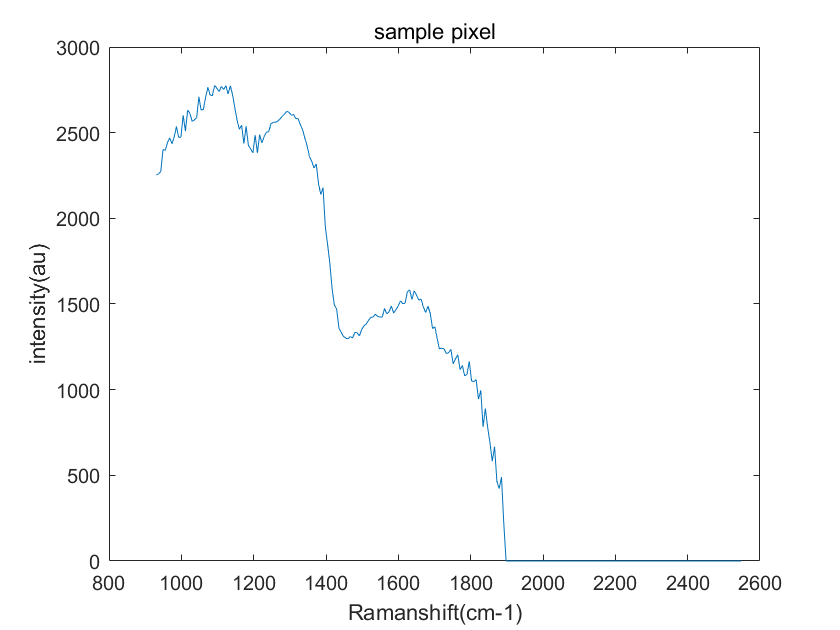

% pixel display %% handi
display_pixel(rawcube, wavelengths, 332, 216);

% effective raman shift 
[~, p1] = min(abs(wavelengths - 1000));

函数或变量 'wavelengths' 无法识别。

[~, p2] = min(abs(wavelengths - 1800));
effwavelengths = wavelengths(p1:p2);

% define effcube
effcube = rawcube(190:500,40:300,p1:p2);
efflines = size(effcube, 1);
effsamples = size(effcube, 2);
effbands = size(effcube, 3);

## mask and roi

% effective band for mask
[~, b] = min(abs(effwavelengths - 1100))

b =     28


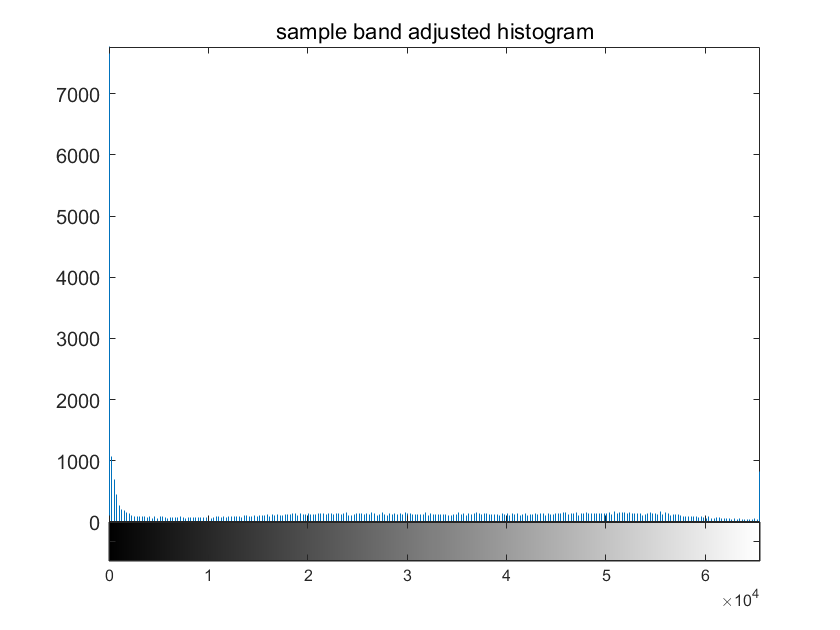

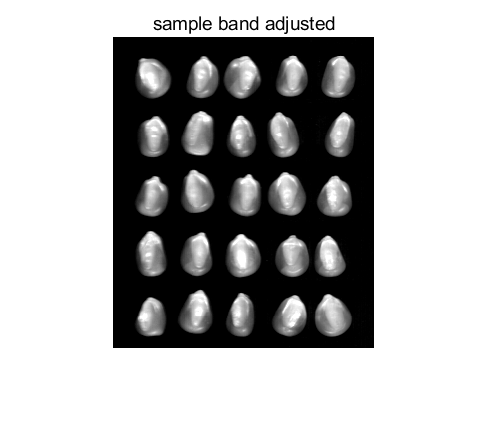

display_band(effcube, b);

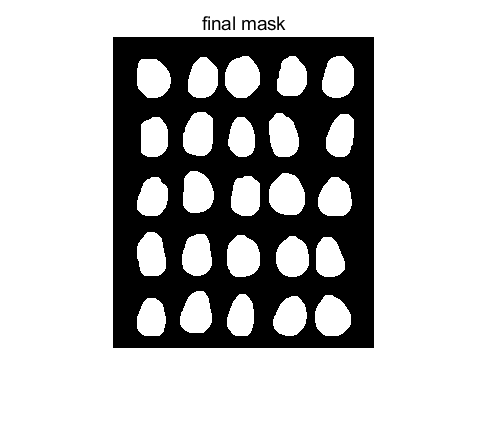

% mask  %% handi
bw = get_mask(effcube, b);

% morphology
se1 = strel('disk', 6);
se2 = strel('disk', 2);
bw_final = imopen(imclose(bw, se2), se1);
bw_final = bwareaopen(bw_final, 500, 8);     
figure; imshow(bw_final); title('final mask')

% roi average data 
tic
[avedata, datalabel] = get_ave_spec(effcube, bw_final);
toc

历时 2.979442 秒。


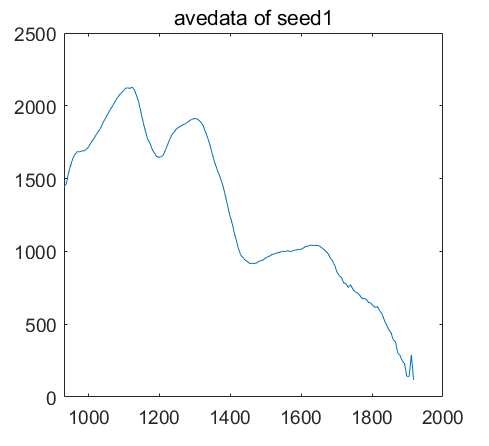

jh_nir900 = avedata;

plot(effwavelengths, avedata(1, :))
title('avedata of seed1')